fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt',...
    '../fabio_data/dhpc09_cnmfe.mat');

nreps = 80;
[mean_err_shuf, mean_err_auto] = deal(zeros(nreps,1));
WaitMessage = parfor_wait(nreps);
parfor i = 1:nreps
    ss_res = fs_sess.decode_spikeshuf(false);
    mean_err_shuf(i) = mean(ss_res.dec_error_spikeshuf);
    ss_res_auto = fs_sess.decode_spikeshuf(true);
    mean_err_auto(i) = mean(ss_res_auto.dec_error_spikeshuf);
    WaitMessage.Send;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).


WaitMessage.Destroy;

save stef_fig_save.mat mean_err_auto mean_err_shuf fs_sess nreps

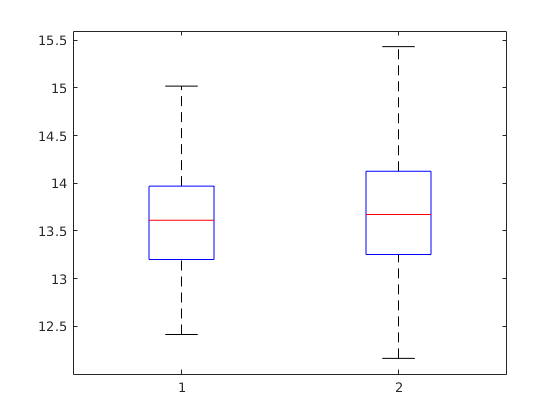

figure;
boxplot([mean_err_auto mean_err_shuf]);

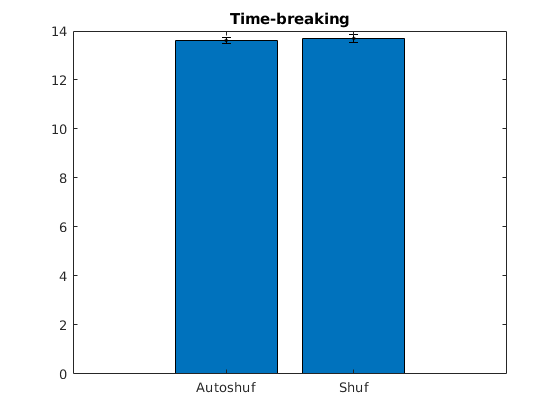

figure;
errnbar([mean(mean_err_auto) mean(mean_err_shuf)], 1.96.*[sem(mean_err_auto) sem(mean_err_shuf)]);
set(gca, 'XTickLabels', {'Autoshuf', 'Shuf'});
title 'Time-breaking'

t_ = tic;
nreps = 80;
WaitMessage = parfor_wait(nreps);
parfor i = 1:nreps
    res(i) = fs_sess.decode_all;
    WaitMessage.Send;
end
WaitMessage.Destroy;
toc(t_)

Elapsed time is 6125.907122 seconds.


save stef_fig_save_res.mat res fs_sess

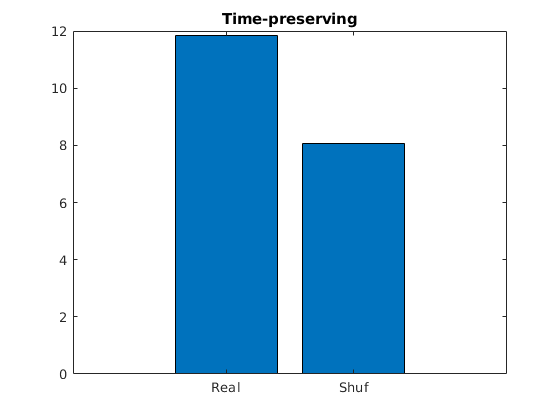

figure;
bar([mean(res.dec_error_real), mean(res.dec_error_shuf)]);
set(gca, 'XTickLabels', {'Real', 'Shuf'});
title 'Time-preserving'

## Testing

fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt',...
    '../fabio_data/dhpc09_cnmfe.mat');

S = full(fs_sess.spike_traces.');
trim_mobile = @(s) s(fs_sess.mobile, :);
Sm = trim_mobile(S);
Xm = trim_mobile(fs_sess.convolve_data(S));

[~, ks_raw] = fs_sess.discrete_pos;
Sm_shuf = @() trim_mobile(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile));
Sm_autoshuf = @() trim_mobile(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile, true));

Xm_shuf = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile)));
Xm_autoshuf = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile, true)));

[X_cont, y_cont, ks, X_spikeshuf, X_spikeshuf_auto] = fs_sess.get_continuous_dataset;

## Trying without convolution

Decoding without convolution

OpenField.decode_all_general(Sm, y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 17.4598
    fs_metric_shuf_mean: 17.4076
    fs_metric_diag_mean: 18.0216


Decoding without convolution, label-shuffle

OpenField.decode_all_general(Sm, y_cont, ks(randperm(numel(ks))), fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 20.1556
    fs_metric_shuf_mean: 20.6778
    fs_metric_diag_mean: 19.7925


Sanity check: decoding a pre-shuffled input, without convolution

OpenField.decode_all_general(Sm_shuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 17.9739
    fs_metric_shuf_mean: 18.9319
    fs_metric_diag_mean: 17.5764


Sanity check: decodng a pre-autoshuffled input, without convolution

OpenField.decode_all_general(Sm_autoshuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 17.7507
    fs_metric_shuf_mean: 17.4492
    fs_metric_diag_mean: 17.9476


Results summary without convolution:

Original = Shuffle-within > Shuffle (in terms of error)

## Trying with convolution

Plain

OpenField.decode_all_general(Xm, y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 9.6746
    fs_metric_shuf_mean: 6.6322
    fs_metric_diag_mean: 10.6089


label-shuffle

OpenField.decode_all_general(Xm, y_cont, ks(randperm(numel(ks))), fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 20.1848
    fs_metric_shuf_mean: 21.1145
    fs_metric_diag_mean: 20.6535


Sanity check: decoding a pre-shuffled input

OpenField.decode_all_general(Xm_shuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 13.7812
    fs_metric_shuf_mean: 6.5237
    fs_metric_diag_mean: 13.8959


Sanity check: decodng a pre-autoshuffled input

OpenField.decode_all_general(Xm_autoshuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims)

ans = struct with fields:
         dec_error_real: [2035×1 double]
         dec_error_shuf: [2035×1 double]
         dec_error_diag: [2035×1 double]
         fs_metric_real: [10×1 double]
         fs_metric_shuf: [10×1 double]
         fs_metric_diag: [10×1 double]
    fs_metric_real_mean: 11.3357
    fs_metric_shuf_mean: 6.3606
    fs_metric_diag_mean: 10.6543


nreps = 20;
WaitMessage = parfor_wait(nreps);
parfor i = 1:nreps
    megares_conv(i) = real_soc_cos(fs_sess, true);
    megares_noconv(i) = real_soc_cos(fs_sess, false);
    WaitMessage.Send;
end
WaitMessage.Destroy;
save stef_fig_save_megares.mat megares_conv megares_noconv fs_sess

bp = comp_struct(megares_conv);
bp.real = bp.real(1:10);
bp_noconv = comp_struct(megares_noconv);
bp_noconv.real = bp_noconv.real(1:10);

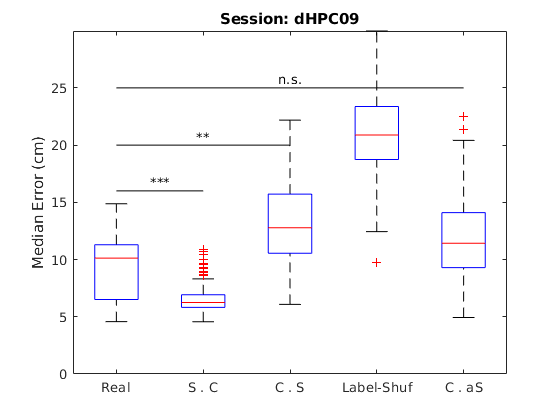

figure;
signif_multibox({bp.real, bp.soc, bp.cos, bp.labelshuf, bp.coas},...
    {'Real', 'S . C', 'C . S', 'Label-Shuf', 'C . aS'},...
    {{'Real', 'S . C'}, {'Real', 'C . aS'}, {'Real', 'C . S'}},...
    [16, 25, 20]);
ylim([0 Inf]);
ylabel 'Median Error (cm)'
title 'Session: dHPC09'

t_ = tic;
res_linear = our_results(69, true) % was with 2.2 tau

res_linear = struct with fields:
    real: 3.5899
     soc: 2.3991
     cos: 7.6142
    coas: 5.2553


toc(t_)

Elapsed time is 282.786089 seconds.


t_ = tic;
res_linear = our_results(69, true) % with 0.5 tau

res_linear = struct with fields:
    real: 3.0011
     soc: 1.8159
     cos: 4.7008
    coas: 4.0916


toc(t_)

Elapsed time is 276.301329 seconds.


t_ = tic;
res_linear = our_results(69, true) % with 0.5 tau
toc(t_)

function s_out = comp_struct(s_in)
F = fields(s_in);
for i = 1:numel(F)
    f = F{i};
    s_out.(f) = vertcat(s_in.(f));
end
end

function megares = real_soc_cos(fs_sess, with_conv)
S = full(fs_sess.spike_traces.');
trim_mobile = @(s) s(fs_sess.mobile, :);

if ~with_conv
    Xm = trim_mobile(S);
else
    Xm = trim_mobile(fs_sess.convolve_data(S));
end

[~, ks_raw] = fs_sess.discrete_pos;

if ~with_conv
    Xm_shuf = @() trim_mobile(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile));
    Xm_autoshuf = @() trim_mobile(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile, true));
else
    Xm_shuf = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile)));
    Xm_autoshuf = @() trim_mobile(fs_sess.convolve_data(fshuffle(S, -ks_raw.*(-1).^fs_sess.mobile, true)));
end

[~, y_cont, ks, ~, ~] = fs_sess.get_continuous_dataset;

res = OpenField.decode_all_general(Xm, y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.real = res.fs_metric_real;
megares.soc = res.fs_metric_shuf;

res = OpenField.decode_all_general(Xm_shuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.cos = res.fs_metric_real;

res = OpenField.decode_all_general(Xm, y_cont, ks(randperm(numel(ks))), fs_sess.bin_nums, fs_sess.box_dims);
megares.labelshuf = res.fs_metric_real;

res = OpenField.decode_all_general(Xm_autoshuf(), y_cont, ks, fs_sess.bin_nums, fs_sess.box_dims);
megares.coas = res.fs_metric_real;
end

function res = our_results(usable_idx, with_conv)
bin_width = 5.9;
tau = 0.5; %2.2
fps = 20;
sm = SessManager;
d = sm.cons_usable(usable_idx);
load(d.source_path);
S = tracesEvents.HD_spikes;
if with_conv
    C = tau_conv(S, tau, fps);
else
    C = S;
end

opt = DecodeTensor.default_opt;
[~, ~, tr_s, tr_e, tr_dir, tr_bins, tr_dir_bins] = DecodeTensor.new_sel(tracesEvents.position(:,1), opt);
data_tensor = DecodeTensor.construct_tensor(C, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.real = err_res.mean_err.unshuffled;
res.soc = err_res.mean_err.shuffled;

within_trial = false(size(tr_dir_bins));
for i = 1:numel(tr_s)
    within_trial(tr_s(i):tr_e(i)) = true;
end

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, false);
if with_conv
    C_shuf = tau_conv(S_shuf, tau, fps);
else
    C_shuf = S_shuf;
end
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.cos = err_res.mean_err.unshuffled;

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, true);
if with_conv
    C_shuf = tau_conv(S_shuf, tau, fps);
else
    C_shuf = S_shuf;
end
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

err_res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, bin_width, my_algs('ecoclin'), [], []);
res.coas = err_res.mean_err.unshuffled;
end

function C = tau_conv(S, tau, fps)
S = S.';

n_frame_div = tau * fps;
assert(n_frame_div > 0);
transient = exp(-(0:50)/n_frame_div);
C = conv2(S, transient, 'full');
C = C(:, 1:size(S,2));

C = C.';
end